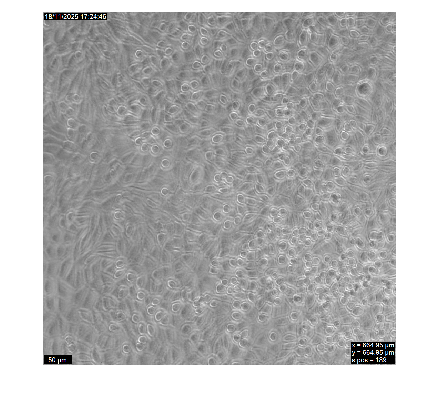

% Image Contrast and Sharpness Characterisation
%
% DESCRIPTION:
%   Loads a grayscale or RGB image and computes two image quality metrics:
%     1. RMS Contrast    — standard deviation of normalised pixel intensities.
%                          Higher values indicate greater contrast.
%     2. Laplacian Variance — variance of the Laplacian-filtered image.
%                             Higher values indicate a sharper image.
%
% INPUTS:
%   - imageFile : The file must be in the current MATLAB working directory.
%                    Accepts any format supported by imread (e.g. .png, .tif).
%                    Supports both RGB and grayscale images.
%
% OUTPUTS:
%   - RMS Contrast and Laplacian Variance printed to the Command Window.
%
% DEPENDENCIES:
%   - Image Processing Toolbox (v 25.2)
%
% USAGE:
%   1. Place your image file in the current MATLAB working directory.
%   2. Set imageFile to your image filename and run the script.
%
% AUTHOR:  Rustam Toshov
% DATE:    April 2026

imageFile = '0. Main.png';

% Load image and convert to normalised grayscale
raw_image = imread(imageFile);
imshow(raw_image)


if size(raw_image, 3) == 3
    % RGB image — convert to grayscale
    gray_image = im2double(rgb2gray(raw_image));
else
    % Already single-channel — use first channel directly
    gray_image = im2double(raw_image(:, :, 1));
end

% RMS Contrast (range between 0 and 1)
rms_contrast = std(gray_image(:));
fprintf('RMS Contrast:       %.4f\n', rms_contrast);

RMS Contrast:       0.0928



% Laplacian Variance
laplacian_response = imfilter(gray_image, fspecial('laplacian', 0), 'replicate');
laplacian_variance = var(laplacian_response(:));
fprintf('Laplacian Variance: %.6f\n', laplacian_variance);

Laplacian Variance: 0.007838
